clear 
clc

## Parameters Pre-setting

V0 = 0.895;                     % input swing
C1 = 38.72E-12;                 % load cap
Fs = 10E6;                      % sample rate
wt = primes(512)                % generate prime number

wt =      2     3     5     7    11    13    17    19    23    29    31    37    41    43    47    53    59    61    67    71    73    79    83    89    97   101   103   107   109   113   127   131   137   139   149   151   157   163   167   173   179   181   191   193   197   199   211   223   227   229


Fin = Fs * wt / 1024            % input frequency (Hz)

Fin = 1.0e+06 *

    0.0195    0.0293    0.0488    0.0684    0.1074    0.1270    0.1660    0.1855    0.2246    0.2832    0.3027    0.3613    0.4004    0.4199    0.4590    0.5176    0.5762    0.5957    0.6543    0.6934    0.7129    0.7715    0.8105    0.8691    0.9473    0.9863    1.0059    1.0449    1.0645    1.1035    1.2402    1.2793    1.3379    1.3574    1.4551    1.4746    1.5332    1.5918    1.6309    1.6895    1.7480    1.7676    1.8652    1.8848    1.9238    1.9434    2.0605    2.1777    2.2168    2.2363


Ron0 = 6.5*4;                  % for m*(W/L) = 16*3u/200n
NUM_FRE = length(wt);           % number of frequency
NUM_SAM = 1024;                 % number of sample point

## Reading simulation waveform

% CSVFILE = 'SD_Exchange_Voutd_Sampled_m8.csv';
% opts = detectImportOptions(CSVFILE);
% preview(CSVFILE, opts)
% opts.SelectedVariableNames = 2 : 2 : NUM_FRE*2;
% M = readmatrix(CSVFILE, opts);
% M(end,:) = [];

## Check the read data

% plot(M(:, 1))
% [r, harmpow, harmfre] = thd(repmat(M(:,end),16,1 ), Fs, 5, 'aliased')

## Get THD from the signal

% HD3_simulation_8 = zeros(1, NUM_FRE);
% for i = 1:NUM_FRE
%     [~, harmpow, ~] = thd(repmat(M(:,i), 4, 1), Fs, 5, 'aliased');
%     HD3_simulation_8(i) = harmpow(3) - harmpow(1);
% end
% 
% HD_temp = getHD_new(Ron0, V0, C1, Fin, -0.2);
% HD3_calculation_m8 = reshape(HD_temp(1,2,:), 1, NUM_FRE);
% HD_temp = getHD_new(Ron0/2, V0, C1, Fin, -0.2);
% HD3_calculation_m16 = reshape(HD_temp(1,2,:), 1, NUM_FRE);


% load('HD3_simulation_m16.mat');
% figure
% semilogx(Fin, HD3_calculation_m8);     % need to be calibration
% hold on;
% semilogx(Fin, HD3_simulation_8);
% semilogx(Fin, HD3_calculation_m16);
% semilogx(Fin, HD3_simulation_16);
% ylim([-180, -75])
% grid on;
% box on;
% xlabel("Frequency [Hz]");
% ylabel("HD3 [dB]");
% legend({'Calculation(m=8)', 'Simulation(m=8)', ...
%     'Calculation(m=16)', 'Simulation(m=16)'}, "Location", "southeast")

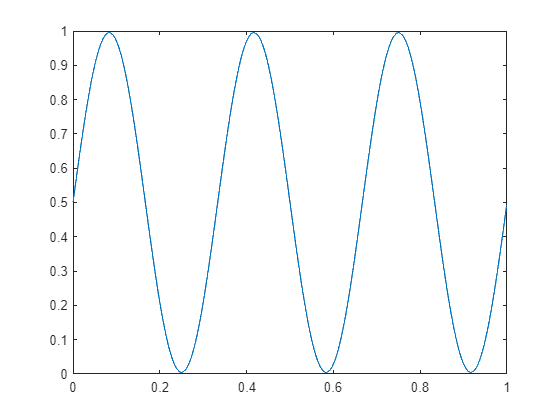

N = 100;
N_sam = 16;
dt = 1 / (N_sam*N);
t = 0:dt:1-dt;
vin = 0.495*sin(2*3*pi*t)+0.5;
figure
plot(t, vin)

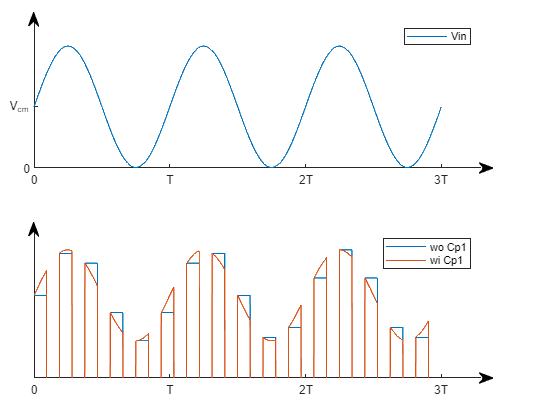

Vgs0 = zeros(1, length(vin));
Vgs1 = zeros(1, length(vin));

for i=1:(1*2*N_sam)
    if (mod(i,2) == 1)
        Vgs0((i-1)*50+1:i*50) = vin((i-1)*50+1) + 1;
        Vgs1((i-1)*50+1:i*50) = vin((i-1)*50+1:i*50) + 1;
    else
        Vgs0((i-1)*50+1:i*50) = 0;
    end
end

figure
% Vgs
subplot(2,1,1)
p = plot(t, vin);
xmax = 1.1;
xlim([0, xmax]);
ylim([0, 1.2]);
% 
legend(['Vin'] , 'Location', 'northeast')
% 
% % 窄边框绘图参数设置
% 
x0_1=0.06;    % 轴框起始点横坐标
% 
y0_1=0.6;    % 轴框起始点纵坐标

width=0.8;  % 轴框宽度

height=0.35; % 轴框高度

% % 轴框位置
% 
pos=[x0_1,y0_1,width,height];

set(gca,'Position',pos);box off
% 
% % 轴框线条属性
% 
% set(gca,'LineWidth',1.5, 'FontName','Times','FontSize',15)
% 
% %轴箭头始终位置与标注
% 
xaPos=x0_1+width;xbPos=xaPos+0.02;
% 
annotation('arrow',[xaPos,xbPos],[y0_1,y0_1],'headStyle','vback2')
% 
% % y轴箭头始终位置与标注
% 
yaPos=y0_1+height;ybPos=yaPos+0.02;
% 
annotation('arrow',[x0_1,x0_1],[yaPos,ybPos],'headStyle','vback2')
% 
% for i=1:2:floor(xmax)*4
%     annotation('line', [x0_1+width*(1/xmax)*i/4, x0_1+width*(1/xmax)*i/4], [y0_1, yaPos], ...
%         'LineStyle','--', 'Color', [0.5,0.5,0.5])
% end
% % annotation('line', [x0+width*(1/xmax)/4, x0+width*(1/xmax)/4], [y0, yaPos], ...
% %     'LineWidth',1.5, 'LineStyle','--', 'Color', [0.5,0.5,0.5])
% % annotation('line', [x0+width*(1/xmax)*3/4, x0+width*(1/xmax)*3/4], [y0, yaPos], ...
% %     'LineWidth',1.5, 'LineStyle','--', 'Color', [0.5,0.5,0.5])
% 
set(gca, 'YTick', [ 0 0.5]);
set(gca, 'YTickLabel', {'0', 'V_{cm}'})
set(gca, 'XTick', [0 0.333, 0.667, 1])
set(gca, 'XTicklabel', {'0', 'T', '2T', '3T'});
set(gca,'XAxisLocation','origin')
% 
% Vin
subplot(2,1,2)
plot(t,Vgs0, t, Vgs1)

ronymax = 1.1;
xlim([0, xmax])
ylim([0.6, 2.2])
% 
legend(['wo Cp1'; 'wi Cp1'] , 'Location', 'northeast')
% 
% 窄边框绘图参数设置

x0_2=0.06;    % 轴框起始点横坐标

y0_2=0.1;    % 轴框起始点纵坐标


% 轴框位置

pos=[x0_2,y0_2,width,height];

set(gca,'Position',pos);box off
% 
% % 轴框线条属性
% % 
% % set(gca,'LineWidth',1.5, 'FontName','Times','FontSize',15)
% 
% x轴箭头始终位置与标注

xaPos=x0_2+width;xbPos=xaPos+0.02;

annotation('arrow',[xaPos,xbPos],[y0_2,y0_2],'headStyle','vback2')

% y轴箭头始终位置与标注

yaPos=y0_2+height;ybPos=yaPos+0.02;

annotation('arrow',[x0_2,x0_2],[yaPos,ybPos],'headStyle','vback2')

% for i=1:2:floor(xmax)*4
%     annotation('line', [x0_2+width*(1/xmax)*i/4, x0_2+width*(1/xmax)*i/4], [y0_2, yaPos], ...
%         'LineStyle','--', 'Color', [0.5,0.5,0.5])
% end
% % annotation('line', [x0, xaPos], [y0+height*(1/ronymax)*0.1, y0+height*(1/ronymax)*0.1], ...
% %     'LineWidth',1.5, 'LineStyle','--', 'Color', [0.5,0.5,0.5])
% 
set(gca, 'YTick', [0.1]);
% set(gca, 'YTickLabel', {'R_{on0}'})
set(gca, 'XTick', [0 0.333, 0.667, 1])
set(gca, 'XTicklabel', {'0', 'T', '2T', '3T'});
set(gca,'XAxisLocation','origin')


% plot(t, Vgs1, t, Vgs0)
% hold on;
% plot(t, vin)
% hold off
% x = (square(2*pi*N_sam*t) + 1) ./ 2;
% plot(t, x)